Import the image

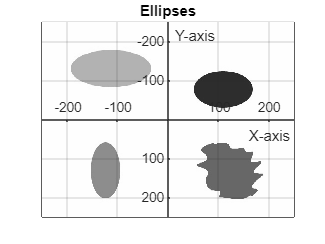

% Load the image
f = imread('4colour_ellipse.jpg');
%imshow(f);
% Convert to grayscale if it's a color image
if size(f, 3) == 3
    f = rgb2gray(f);
end
f = double(f);
plot_ellipse(f , 0, 0)

Compute the 2-dimensional Gaussian function values

sigma = 1; % standard deviation for Gaussian

G = gaussian_function(sigma);

Compute the 2d-convolution

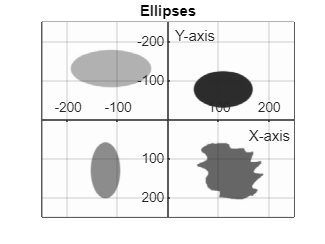

f_smooth = conv2(f, G, 'same');
plot_ellipse(f_smooth, 0 ,0)

An edge is defined when

[df_smooth_x, df_smooth_y] = gradient(f_smooth);
gradient_norm = sqrt(df_smooth_x.^2 + df_smooth_y.^2);

is large, and when

M = mexican_hat(sigma);
d_f_smooth_2 = conv2(f, M, 'same');
df_smooth_2_abs=abs(d_f_smooth_2);

is small.

Detect all edged:

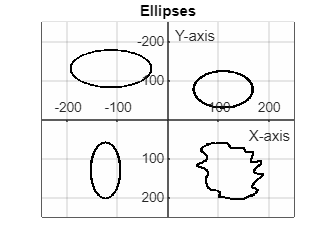

f_feature = canny_edge_detector(gradient_norm, df_smooth_2_abs, 5, 400);
plot_ellipse(f_feature, 0,0)

F = feature_set(f_feature);

Clustering:

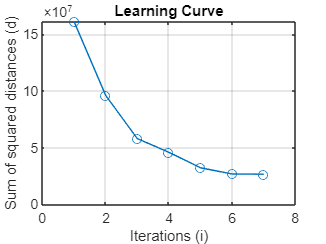

n = 4; % Number of clusters
I_max = 30; % Max number of iterations 

[color_matrix, cluster_points] = clustering(n, I_max, F, f_feature);

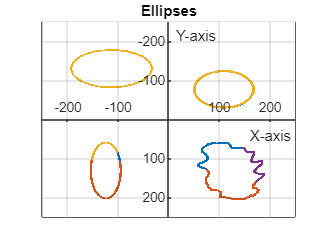

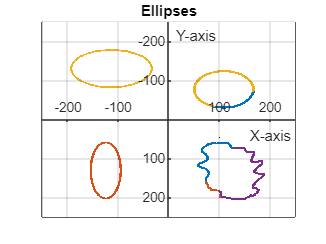

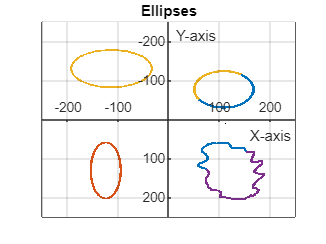

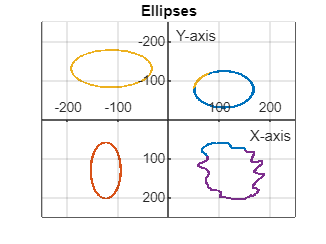

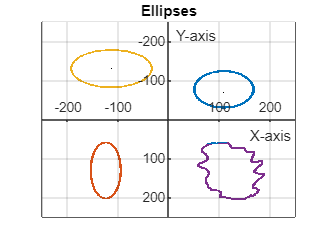

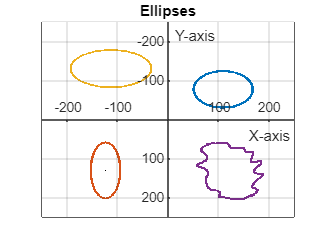


for i=1:length(color_matrix)
    plot_ellipse(color_matrix{i}, 0,0)
end

Least Squares Classification, C1:

PD = "Solution has a PD Q, det(Q)>0"

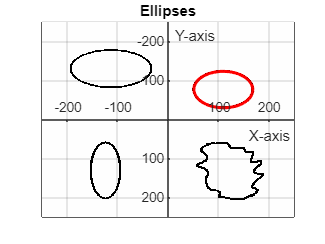

PD = "Solution has a PD Q, det(Q)>0"

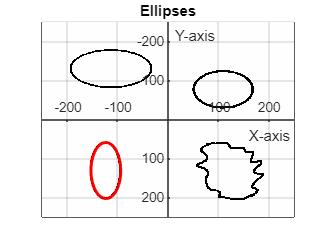

PD = "Solution has a PD Q, det(Q)>0"

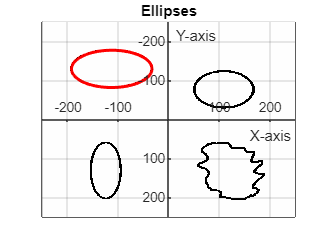

PD = "Solution has a PD Q, det(Q)>0"

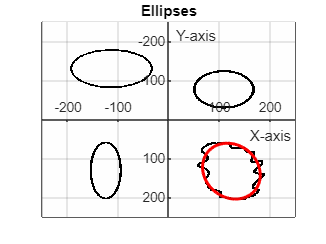

%Classification1 = least_squares_classification(f, F);

for i=1:n
    [Classification, PD] = least_squares_classification(f, cluster_points{i});
    display(PD);
    plot_ellipse(f_feature, Classification, 1);
end

%plot_ellipse(f_feature, Classification2, 1);

function [classification, PD] = least_squares_classification(f, F)
%First center F in the origin
[imageHeight, imageWidth, ~] = size(f);

F_centered = F;  

% Shift the coordinates
F_centered(:, 2) = F(:, 1) - imageWidth / 2;  % Map x-coordinates
F_centered(:, 1) = F(:, 2) - imageHeight / 2; % Map y-coordinates

% Now F_centered has the coordinates with the origin at the center

%Initialize Parameters
length(F_centered);
V = ones(length(F_centered), 1);
M = zeros(length(F_centered), 5);
Q = zeros(2,2);
d = zeros(2,1);
e = 1;

for i = 1:length(F_centered)
    M(i, 1) = F_centered(i, 1)^2;
    M(i, 2) = 2*F_centered(i, 1)*F_centered(i, 2);
    M(i, 3) = F_centered(i, 2)^2;
    M(i, 4) = 2*F_centered(i, 1);
    M(i, 5) = 2*F_centered(i, 2);
end
%Calculate and extract optimal Parameters
theta_optimal = -inv(M'*M) * M' *V;

Q(1,1:2) = theta_optimal(1:2,1);
Q(2,1:2) = theta_optimal(2:3,1);
d = theta_optimal(4:5,1);

if det(Q) > 0
    PD = "Solution has a PD Q, det(Q)>0";
else
    PD = "Error: Solution does not have PSD Q, det(Q)<=0";
end

% Define equation for Ellipse in Q,d in order to plot
classification = @(x, y) [x, y] * Q * [x; y] + 2 * d' * [x; y] + 1;

end

function G = gaussian_function(sigma)
    % Define the kernel size
    size = 2 * ceil(3 * sigma) + 1;
    
    % Create the coordinate grid
    x = -(size - 1) / 2 : (size - 1) / 2;
    
    % Define the 1D Gaussian function
    g = (1 / (sigma * sqrt(2 * pi))) * exp(-(x .^ 2) / (2 * sigma ^ 2));
    
    % Compute the 2D Gaussian kernel using outer product
    G = g' * g;
end

function f_feature = canny_edge_detector(gradient_norm, df_2_smooth_abs, d1, d2)
    [n, m] = size(gradient_norm);
    f_feature = 255*ones(n, m);  % Or preallocate a numeric matrix if possible
    
    % Define boundary offset to avoid detecting edges near the boundary
    offset = 3; 
    % Loop through each unique pair
    for i = (1 + offset):(n - offset)
        for j = (1 + offset):(m - offset)
            if (gradient_norm(i,j) > d1) && (df_2_smooth_abs(i,j) < d2)
            % Put the pair (i,j) in the feature set
            f_feature(i, j) = 0;
            end
        end
    end
end

function M = mexican_hat(sigma)
    % Define the kernel size
    size = 2 * ceil(3 * sigma) + 1;
    
    % Create the coordinate grid
    [x, y] = meshgrid(-(size - 1) / 2 : (size - 1) / 2);

    % Define the Mexican Hat function
    M = (x.^2 + y.^2 - 2 * sigma^2) ./ (sigma^4) .* exp(-(x.^2 + y.^2) / (2 * sigma^2));
end

function plot_ellipse(img, classificationArray, plotClassification)
    %Get image dimensions
    [imageHeight, imageWidth, ~] = size(img);
    
    % Display the image
    figure;
    image(img, 'XData', [-imageWidth/2, imageWidth/2], 'YData', [-imageHeight/2, imageHeight/2]);
    colormap gray;
    %hold on;
    
    % Set up the axes
    ax = gca;
    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
    
    % Define the axis limits to match the image dimensions
    xlim([-imageWidth/2, imageWidth/2]);
    ylim([-imageHeight/2, imageHeight/2]);
    
    % Enable grid
    grid on;
    hold on;
    % Label axes
    xlabel('X-axis');
    ylabel('Y-axis');
    title('Ellipses');
    
    if plotClassification ==1 %plot classification over feature set or original image.
        x_range = linspace(- imageWidth/2, imageWidth/2, imageWidth);  % Range set by image size
        y_range = linspace(-imageHeight/2, imageHeight/2, imageHeight);
        [X, Y] = meshgrid(x_range, y_range);
        Z = arrayfun(classificationArray, X, Y);
        contour(X, Y, Z, [0, 0], 'LineWidth', 2, 'EdgeColor', 'r');
    end
end

function F = feature_set(f_feature)
    [n, m] = size(f_feature);
    F = [];  % Or preallocate a numeric matrix if possible
    % Loop through each unique pair
    for i = 1:n
        for j = 1:m
            if f_feature(i,j) == 0
            % Put the pair (i,j) in the feature set
            F = [F; [i j]];
            end
        end
    end
end

function [color_matrix, cluster_points] = clustering(n, I_max, F, f_feature)
    [N, ~] = size(F);
    centroids = F(randperm(N, n), :); % Initial centroids chosen randomly from F
    clusters = cell(1, n);
    d = []; 
    color_matrix = {}; 
    cluster_points = {}; 
    %Clustering
    for i = 1:I_max
        distances = zeros(N, n);
        % Step 1: Assign points to the nearest centroid
        for k = 1:n     
            % Compute the Euclidean distance from all points in F to the k-th centroid
            distances(:, k) = sqrt(sum((F - centroids(k, :)).^2, 2));
        end
        
        % Find the closest centroid for each point
        [min_distances, min_idx] = min(distances, [], 2);
        
        % Total sum of squared distances of the clustered data points to their centroids
        d = [d sum(min_distances.^2)];
       
        new_centroids = zeros(n, 2);
    
        for k = 1:n
            % Assign the points to the respective cluster
            clusters{k} = find(min_idx == k);
        end
    
        % Step 2: Update centroids to the mean of assigned points
        for k = 1:n
            if ~isempty(clusters{k})
                new_centroids(k, :) = round(mean(F(clusters{k}, :), 1));
            else
                % If a cluster has no points, keep its centroid unchanged
                new_centroids(k, :) = centroids(k, :);
            end
        end
        
        % Step 3: Check for convergence (if centroids do not change)
        if all(centroids == new_centroids)
            break; % Convergence achieved
        end
        centroids = new_centroids; % Update centroids
    
        [imageHeight, imageWidth, ~] = size(f_feature);
        % Initialize an RGB matrix with all black pixels
        color_matrix{i} = 255*ones(imageHeight, imageWidth, 3);
        
        % Generate n distinguishable colors using lines colormap
        colors = lines(n);
        
        % Assign color to each cluster point in the RGB matrix
        for k = 1:n
            % Find the points in the current cluster
            cluster_points{k} = F(clusters{k}, :);
            
            for p = 1:size(cluster_points{k}, 1)
                % Get the matrix coordinates for each point in the cluster
                row = cluster_points{k}(p, 1);
                col = cluster_points{k}(p, 2);
                
                % Place the color of cluster k at (row, col)
                color_matrix{i}(row, col, :) = colors(k, :);
            end
        end
    
        % Place centroids in white (optional)
        for c = 1:size(centroids, 1)
            row = centroids(c, 1);
            col = centroids(c, 2);
            color_matrix{i}(row, col, :) = [0, 0, 0]; % Black color for centroids
        end
    end

    % Plot the learning curve
    figure;  
    plot(1:length(d), d, '-o'); 
    xlabel('Iterations (i)');  
    ylabel('Sum of squared distances (d)'); 
    title('Learning Curve');  
    grid on;  
end